# Homework 2

### Problem 0. Download the .mat file.

file = matfile('D:\Src\Matlab\Statistical data analyze\Hometasks\Homework2.mat');


### Problem 1. Draw a line plot that shows the Gaussian probability distribution with mean 50 and standard deviation 10. Label the axes.

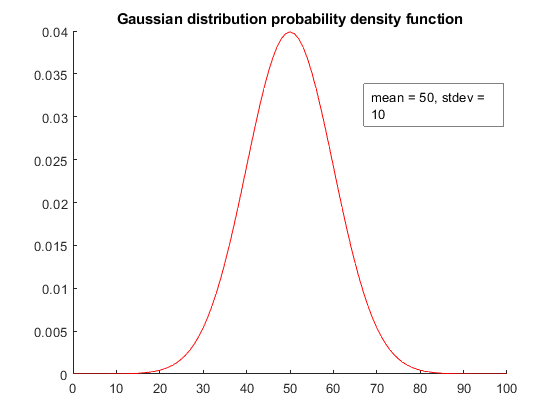

pd = makedist('Normal','mu',50,'sigma',10);
x = 0:100;
pdensity = pdf(pd, x);
figure('Name', 'Gaussian distribution probability density function'); hold on;
plot(x, pdensity, 'r-');
title('Gaussian distribution probability density function')
annotation('textbox', [.65 .7 .25 .1], 'String', 'mean = 50, stdev = 10');
hold off;

### Problem 2. The data1 variable in Homework2.mat is a matrix of dimensions 3 x 20. Each row contains measurements obtained for a distinct group of subjects. We are interested in assessing whether there are any differences across the three groups. The metric that we will use is variability in the group means (i.e. compute the mean of each group and then compute the standard deviation across the three mean values). If this variability is high, that would suggest that the groups are different, whereas if the variability is low, that would suggest that the groups are the same. Use randomization to test the null hypothesis that all three groups come from the same underlying distribution. Run 10,000 simulations and calculate a one-tailed p-value. Echo the computed p-value to the screen.


data1 = file.data1;
means = [mean(data1(1,:)) mean(data1(2,:)) mean(data1(3,:))];
origdev = std(means);
%A variable containing a sum of the deviations that a more extreme than
%origina deviation
extdevs = 0;

for i=1:10000
    x = shuffle(data1);
    dev = std([mean(x(1,:)) mean(x(2,:)) mean(x(3,:))]);
    if (dev > origdev)
        extdevs = extdevs + dev;
    end
end
pvalue = extdevs/10000;
fprintf('P-value: %f \n', pvalue);

P-value: 0.006552 


### Problem 3. Suppose we measure a group of 100 subjects before and after a certain manipulation. The data2a variable in Homework2.mat is a vector of dimensions 1 x 100 with the pre-manipulation measurement, and the data2b variable in Homework2.mat is a vector of dimensions 1 x 100 with the post-manipulation measurement. Quantify the manipulation effect by subtracting the pre-manipulation from the post-manipulation measurement. Then use bootstrapping to test the null hypothesis that the differences come from a probability distribution with mean 0. Run 10,000 simulations and calculate a two-tailed p-value. Echo the computed p-value to the screen.


data2a = file.data2a;
data2b = file.data2b;
diff = data2b - data2a;
avgdiff = mean(diff);

x = diff - mean(diff);
pvalue = 0;

for i=1:10000
ix = ceil(length(x)*rand(1,length(x)));
    if (abs(mean(x(ix))) > abs(avgdiff))
        pvalue = pvalue + abs(mean(x(ix)));
    end
end
pvalue = pvalue / 10000;
fprintf('P-value: %f \n', pvalue);

P-value: 0.009160 


### Problem 4. Flip a coin n times and count the number of heads obtained. Repeat this 10,000 times and visualize the distribution of results using a histogram. Perform this simulation for different n values (n = 10, 100, 1000) and show the resulting histograms on three different subplots of a single figure. For each subplot, label its axes and provide a title.

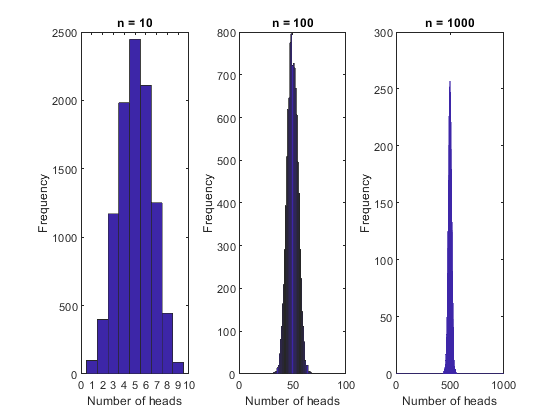



n = [10 100 1000];
figure;
for i = 1:numel(n)
    tosses = randi([0 1], 10000, n(i));
    counts = sum(tosses==1,2);
    subplot(1,3,i);
    hist(counts,0:1:n(i));
    ax = axis;
    axis([0 n(i) ax(3:4)]);
    xlabel('Number of heads');
    ylabel('Frequency');
    title(sprintf('n = %d',n(i)));
end

### Function for reshuffling (randomization)

function f = shuffle(A)
    out = reshape(A, 1, []);
    out = out(randperm(length(out)));
    f = reshape(out, size(A));
end